# Clear console and workspace and add project root to path

close all;
project_root='D:\Chandhar_labs\DroneSwarm';
addpath(genpath(project_root));

## Call parameters files and initialisation variables

PATH_COMPLETED = false;
MOBILITY_MODEL = 1; % 1 for surveillance and 0 for generic
DRONE_TYPE="quadcopter";
SIMULATION_REALISTIC= true;
ROTATIONAL_MODEL= false;
ACTIVE_ENVIRONMENT = false;
DEBUG = false;
VIDEO = false;
CENTER_VIEW_ON_SWARM = true;
%FREQ=10^7;
%antennapos=[0 0 0];

h1=animatedline;
fontsize = 12;
run('param_sim.m');
run('param_battery');
run('param_physics');
run('param_swarm');
run('param_GS.m');

p_GS.Mx=8;
p_GS.My=8;
%FREQ= p_GS.freq;

if DRONE_TYPE == "fixed_wing" || DRONE_TYPE == "quadcopter"
    run('param_drone.m');
elseif DRONE_TYPE == "point_mass"
    run('param_drone.m');
end
run('param_map');

if DRONE_TYPE == "point_mass"
    SWARM_VIEWER_TYPE = "agent";
elseif DRONE_TYPE == "quadcopter"
    SWARM_VIEWER_TYPE = "drone";
end

## Init Swarm object, Wind, Viewer and other variables

% Init swarm and set positions
scale=1;
x1=-3000*scale;
x2=6000*scale;
y1=4000*scale;
y2=12000*scale;
GSD=(2e-1)*scale;
FL=(5e-3)*scale;
PS=(2.3e-6)*scale;

swarm = Swarm();

drones_x=5;
drones_y=4;
p_swarm.nb_agents=drones_y*drones_x;
%swarm.nb_agents=p_swarm.nb_agents;
swarmpos=[];
for i = 1 : p_swarm.nb_agents
    swarm.add_drone(DRONE_TYPE, p_drone, p_battery, p_sim, p_physics,map);
end
swarm.add_GS(p_GS.Mx,p_GS.My, p_GS.Az, p_GS.El,p_GS.freq,p_GS.N0,p_GS.bw,p_GS.pu);
for j=1:drones_y
    for i=1:drones_x
%         x=x1+(i-1)*((x2-x1)/5);
%         y=y1+(j*(y2-y1)/4);
%         z=0;
        k=5*(j-1)+i;
        swarmpos(:,k)=[x1+(i-1)*((x2-x1)/5);y1+(j*(y2-y1)/4);0];
    end
end
swarm.set_pos(swarmpos)
% Init wind
wind = zeros(6,1); % steady wind (1:3), wind gusts (3:6)

% Init viewer
swarm_viewer = SwarmViewer(p_sim.dt_plot, CENTER_VIEW_ON_SWARM);
swarm_viewer.viewer_type = SWARM_VIEWER_TYPE;
states_handle = [];
%plot variables
% colour={'#FF0000','#00FF00','#0000FF','#00FFFF','#FF00FF','#FFFF00','#000000','#0072BD','#D95319','#EDB120','#7E2F8E','#77AC30','#4DBEEE','#A2142F'};
% f1=figure;
% up_c=gobjects(swarm.nb_agents,1);
% for i=1:swarm.nb_agents
%     up_c(i)=animatedline('color',string(colour(mod(i,14)+1)));
% end
% ylabel("Uplink Capacity");
% %legend({'Drone1','Drone2','Drone3','Drone4','Drone5','Drone6','Drone7','Drone8','Drone9','Drone10','Drone11','Drone12'});
% hold on
% f2=figure;
% up_t=gobjects(swarm.nb_agents,1);
% for i=1:swarm.nb_agents
%     up_t(i)=animatedline('color',string(colour(mod(i,14)+1)));
% end
% ylabel("Uplink Throughput");
% hold on
% f3=figure;
% b_l=gobjects(swarm.nb_agents,1);
% for i=1:swarm.nb_agents
%     b_l(i)=animatedline('color',string(colour(mod(i,14)+1)));
% end
% ylabel("Battery Voltage");
% hold on
% f4=figure;
% up_p=gobjects(swarm.nb_agents,1);
% for i=1:swarm.nb_agents
%     up_p(i)=animatedline('color',string(colour(mod(i,14)+1)));
% end
% ylabel("Uplink link Tx power");
% hold on
% %Plot of drone path
% f5=figure;
% d_t=gobjects(swarm.nb_agents,1);
% for i=1:swarm.nb_agents
%     d_t(i)=animatedline('color',string(colour(mod(i,14)+1)));
% end
% ylabel("Drone trajectory");
% hold on
% %legend({'Drone1','Drone2','Drone3','Drone4','Drone5','Drone10','Drone15','Drone20'});

## Main simulation loop

kp=[0.8,0.8,0.8];
ki=[0,0,0];
kd=[0.4,0.4,0.4];
vel=zeros(1,3);
error=zeros(1,3);
error_prev=zeros(1,3);
error_sum=zeros(1,3);
error_diff=zeros(1,3);
velsat=5;
threshold=10;
disp('Type CTRL-C to exit');

Type CTRL-C to exit


equivalent_drone = swarm.get_barycenter();
equivalent_drone.autopilot_version=4;
 display(equivalent_drone.pos_ned)

         600
        9000
           0



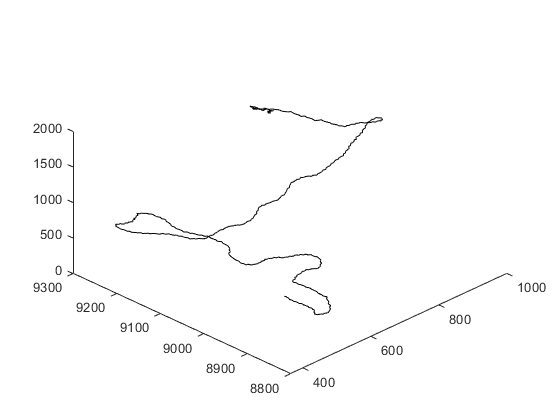

waypoints=get_waypoints(equivalent_drone.pos_ned',drones_x,drones_y,x1,x2,y1,y2,GSD,FL,PS);
%plot3(waypoints(:,2),waypoints(:,1),-waypoints(:,3))
j=1;
angular_velocity=10;
for time = p_sim.start_time:p_sim.dt:p_sim.end_time
    
    
    %%%%%%%%%%%%%%%%%%% ROTATIONAL MODEL%%%%%%%%%%%%%%%%%%%%%%%%%
            
            
          if ROTATIONAL_MODEL == true
              if mod(time,3) == 0
                  
              end
          end
        
    
    
    if MOBILITY_MODEL == 1
      %%%%%%%%%%%%%%%%%%%%%%%   SURVEILLANCE MODEL %%%%%%%%%%%%%%%%%%%%%%%%%%%
        if PATH_COMPLETED == false
            
            if norm(equivalent_drone.pos_ned.'-waypoints(j,:)) <= threshold
                j=j+1
                %display(j)
            end
            if j>length(waypoints(:,1))
                PATH_COMPLETED= true;
                waypoints(j,:)=mean(swarmpos,2);
                break; 
            end
%         else
%             %return home
%             if norm(equivalent_drone.pos_ned.'-waypoints(j,:)) <= threshold
%                 j=j+1;
%             end
%             if j>length(waypoints(:,1))
%                 break; 
%             end
        end
%             error=equivalent_drone.pos_ned'-waypoints(j,:);
%             error_diff=error-error_prev;
%             error_sum=error_sum+error;
%             vel=kp.*error + ki.*error_sum + kd.*error_diff;
%             error_prev=error;
%             
%             k=vel>velsat;
%             vel(k)=velsat;
%             k=vel<-velsat;
%             vel(k)=-velsat;
%             vel=-vel;
            
            %equivalent_drone.command=[0;waypoints(j,1);waypoints(j,2);-waypoints(j,3)];
            equivalent_drone.command=[0;0;0;0];
            equivalent_drone.update_state(wind,time,1);
                
            %swarm.set_vel_pid(vel.');
            %uplink capacity plot
            if mod(time,1)==0
%                     addpoints(h1,equivalent_drone.pos_ned(1),equivalent_drone.pos_ned(2),-equivalent_drone.pos_ned(3));
%                     drawnow update;
%                     hold on;
%             end
%                 if sum([swarm.drones.V]<0)>0
%                     break;
%                 end

%                 %Drone trajectory plot
                 for i=1:1
                     addpoints(h1,equivalent_drone.pos_ned(1),equivalent_drone.pos_ned(2),equivalent_drone.pos_ned(3))
                     view(-45,45);
                 end
                 drawnow update;
                 hold on;
            end   

            
            %swarm.update_state(wind, time , p_GS.freq);
            %swarm_viewer.update(time, swarm, map);
            %equivalent_drone = swarm.get_barycenter();
            
%     else
%         %%%%%%%%%%%%%%%%%%%%   GENERIC MODEL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%         
%         %             pose = equivalent_drone.pos_ned;
%         %             p1=swarm.drones(1).pos_ned;
%         %             p2=swarm.drones(5).pos_ned;
%         %             p3=swarm.drones(16).pos_ned;
%         %             p4=swarm.drones(20).pos_ned;
%         %             p5=swarm.drones(13).pos_ned;
%         if mod(time,1)==0
%             addpoints(h1,pose(2),pose(1),-pose(3));
%             addpoints(h2,p1(2),p1(1),-p1(3));
%             addpoints(h3,p2(2),p2(1),-p2(3));
%             addpoints(h4,p3(2),p3(1),-p3(3));
%             addpoints(h5,p4(2),p4(1),-p4(3));
%             addpoints(h6,p5(2),p5(1),-p5(3));
%             drawnow update;
%             view(-45,45);
%             hold on;
%         end
%         
%         
%         swarm.update_state(wind, time , p_GS.freq);
%         swarm_viewer.update(time, swarm, map);
%         
%         
     end
end


% Close all plots%
%close all;


